# Weight Initialisation and Neural Network Cost Function

In this tutorial you will develop a function to initialise the weight matrix of a neural network and the cost function for the neural network in `MATLAB`.

## Set up Environment

clc, clear, close all
addpath('lib')

## Weight Initialisation

Develop a function called `rand_initialize.m` to initialise the weight matrix of a neural network. The code should be flexible for any number of inputs or neurons in any layer.

**To test your function we can imagine an example architecture with:**

- 6 input features

- 15 neurons in the hidden layer

- 1 neuron in the output layer

#### Function Inputs                                                        Function Outputs

Number of neurons in the previous/input                         Randomly initialised weight matrix

Number of neurons in the next/output layer

#### **Calculate the first layer weights:**

fprintf('Shape of W1 should be:\t[15, 7]')

Shape of W1 should be:	[15, 7]

**Uncomment the code below to test your code.**

W1 = weights_init(6, 15);
fprintf('Shape of W1 is:\t\t[%i, %i]', size(W1, 1), size(W1, 2))

Shape of W1 is:		[15, 7]

#### **Calculate the second layer weights:**

fprintf('Shape of W2 should be:\t[1, 16]')

Shape of W2 should be:	[1, 16]

**Uncomment the code below to test your code.**

W2 = weights_init(15, 1);
fprintf('Shape of W2 is:\t\t[%i, %i]', size(W2, 1), size(W2, 2))

Shape of W2 is:		[1, 16]

## Neural Network Cost Function

In this task, you must develop the regularized cost function for solving a multiclass classification problem using neural networks.

### **The cost function**


$$J\left(\mathit{\mathbf{w}}\right)=\frac{1}{n}\;\left(\sum_{k=1}^K \;\sum_{i=1}^n -y_k^{\left(i\right)} \log \left({h\left({\mathit{\mathbf{x}}}^{\left(i\right)} ,\mathit{\mathbf{w}}\right)}_k \right)-\left(1-y_k^{\left(i\right)} \right)\log \left(1\;-{h\left({\mathit{\mathbf{x}}}^{\left(i\right)} ,\mathit{\mathbf{w}}\right)}_k \right)\right)+\frac{\lambda }{2m}\sum_{l=1}^{L-1} \sum_{i=1}^{\textrm{sl}} \sum_{j=1}^{\textrm{sl}+1} {\left(w_{\textrm{ij}}^{\left(l\right)} \right)}^2 \;\;\;$$


The parameter vector $\textbf{w}$ is determined so that the hypothesis $h_w (\textbf{x},\textbf{w})=\hat{y}$ is close to$y$ for the training examples while satisfying the regularization penalty. 

### **The hypothesis**


$$h\left({\mathit{\mathbf{x}}}^{\left(i\right)} ,\mathit{\mathbf{w}}\right)=\phi \left({\mathit{\mathbf{x}}}^{\left(i\right)} \cdot \;w\right)$$


The activation function $\phi$ should be treated as a hyperparameter of the model. Your code should be flexible enough to change the function as required. There are many ways to do this in `MATLAB `i.e., using the `eval `function or passing the activation function handle (`@ function`) into your cost function.

### **Wrapping the Weights**

One of the challenges of this task is structuring the weight matrix in way to use your neural network cost function with a gradient based optimiser. Optimisers like '`fmincg.m' `need the weights and their respective gradients (for the entire network) to be formatted in a single columm vector, so your cost function will have to 'unravel' and reshape the weights into a matrix. To do this, we recomend passing the architecture of the network into the cost function, and leveraging the inbuilt `reshape` function.

### **Handling the target vector**

To solve multiclass classification problems you need to create an encoded target vector so that the bounds of target stay within the range [0, 1]. You can decide whether to handle this nuance inside your cost function or before you pass the data. Either way, you want to transform the target vector so there is the same number of columns as there is unique classes, where there are 0s in all of the columns with the exception of one, so that a 1 in column C indicates that the sample belongs to class C.

### **The bias**

You should remember to include the bias unit for each layer. In this implementation the bias is handled within the cost function so we do not need to explicitly define it.

### **The function output**

Your cost function needs to output the cost and gradient (in that order) to work with the optimizers we are going to use for the weight training.

**In a file named '**`nnCostFunction.m`**' implement the regularized cost function for a neural network, and store the funtion in the 'lib' folder.**

#### Function Inputs                                                        Function Outputs

Weights - $W$                                                                    Cost - $J$

Architecture - n_input, n_hidden, n_output                      Gradient - grad

Training data - $X\;\&\;y$                                                       

Regularization penalty -  $\lambda$ 

Activation Function - act_fun

## Test your function

Test the `nnCostFunction.m` file on the following data and check your results against the answer below.

samples = 80;

r1 = 1/3;
r2 = 2/3;
r3 = 1;

theta = linspace(0,6*pi,samples)';

X = [(r1*cos(theta)), (r1*sin(theta));
     (r2*cos(theta)), (r2*sin(theta));
     (r3*cos(theta)), (r3*sin(theta))];

y = [ones(samples,1); 2*ones(samples,1); 3*ones(samples,1)];
classes = unique(y);

### Plot the toy data

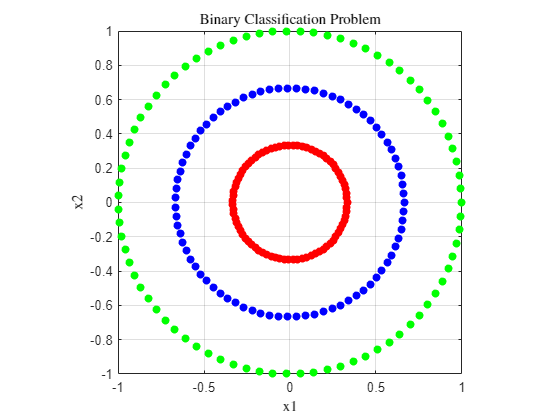

figure, hold on, box on, grid on
colo = ['r'; 'b'; 'g'];
for c = 1:length(classes)
    plot(X(y==classes(c),1),X(y==classes(c),2),['o',colo(c)],'markersize',3,'linewidth',3)
end
title('Binary Classification Problem', "Interpreter", "Latex")
xlabel('x1', "Interpreter", "Latex")
ylabel('x2', "Interpreter", "Latex")
axis square

#### **Define Model Architecture**

n_input = size(X, 2);
n_hidden = 10;
n_output = length(unique(y));

#### **Define Model Hyperparameters**

lambda = 0.1;
act_fun = 'sigmoid';

#### Weight Initialisation

We need to reformat the weights into a single column vector to work with the optimisers that we will leverage for the weight training.

rng(1)
nW = 2;  % number of layers minus 1

W1 = weights_init(n_input, n_hidden);
W2 = weights_init(n_hidden, n_output);

Weights = [W1(:); W2(:)];  % basically doing the tf.keras function Layers.flatten()

**Encode Target Vector**

y_encoded = zeros(size(y, 1), n_output);
for i = 1:length(y)
    if y(i) == 1
        y_encoded(i, 1) = 1;
    elseif y(i) == 2
        y_encoded(i, 2) = 1;
    else
        y_encoded(i, 3) = 1;
    end
end
y = y_encoded;

**Scale Features**

% [X,centerValue,scaleValue] = normalize(X,"range");

**Check results**

fprintf('My results are: J = %2.2f \nThe shape of grad is: (%2i, %2i)', 2.07, [63, 1])

My results are: J = 2.07 
The shape of grad is: (63,  1)

**Uncomment the code below to test your code.**

Note that in this example, we handle the encoding of the target vector inside the function.

[J, grad] = nnCostFunction(Weights, n_input, n_hidden, n_output, X, y, lambda, act_fun);
fprintf('The results are: J = %2.2f \nThe shape of grad is: (%2i, %2i)', J, size(grad))

The results are: J = 2.90 
The shape of grad is: (63,  1)